# Tuning Waypoint Follower for Fixed-Wing UAV

This example designs a waypoint following controller for a fixed-wing unmanned aerial vehicle (UAV) using the [**UAV Guidance Model**](docid:uav_ref#mw_646d746b-9b4d-4f96-9463-f42cbaa5d228) and [**UAV Waypoint Follower**](docid:uav_ref#mw_39443a5e-bef5-4e50-a65d-51ddbdf4b243) blocks.

The example iterates through different control configurations and demonstrates UAV flight behavior by simulating a kinematic model for fixed-wing UAV.

## Guidance Model Configuration

The fixed-wing guidance model approximates the kinematic behavior of a closed-loop system consisting of the fixed-wing aerodynamics and an autopilot. This guidance model is suitable for simulating small UAV flights at a low-fidelity near the stable flight condition of the UAV. We can use the guidance model to simulate the flight status of the fixed-wing UAV guided by a waypoint follower.

The following Simulink® model can be used to observe the fixed-wing guidance model response to step control inputs.

open_system('uavStepResponse');

## Integration with Waypoint Follower

The `fixedWingPathFollowing` model integrates the waypoint follower with the fixed-wing guidance model. This model demonstrates how to extract necessary information from the guidance model output bus signal and feed them into the waypoint follower. The model assembles the control and environment inputs for the guidance model block.

open_system('fixedWingPathFollowing');

## Waypoint Follower Configuration

The waypoint follower controller includes two parts, a **UAV Waypoint Follower** block and a fixed-wing UAV heading controller.

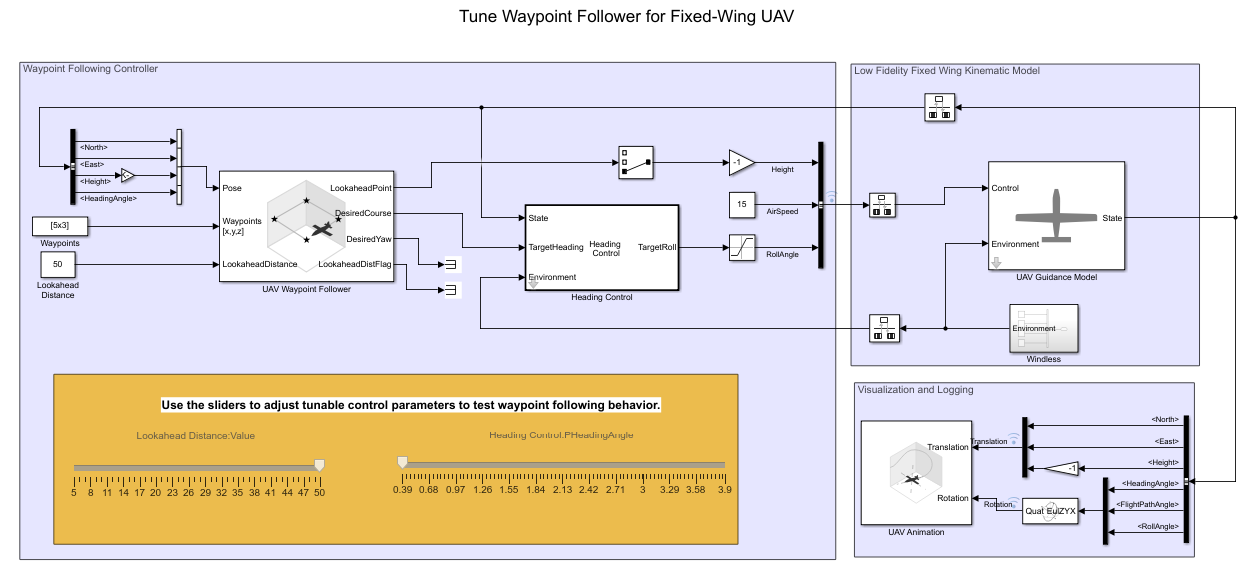

The UAV Waypoint Follower block computes a desired heading for the UAV based on the current pose, lookahead distance, and a given set of waypoints. Flying along these heading directions, the UAV visits each waypoint (within the specified transition radius) in the list.

The Heading Control block is a proportional controller that regulates the UAV heading angle by controlling the roll angle under the coordinated-flight condition.

The [**UAV Animation**](docid:uav_ref#mw_f601848e-8b15-4e7c-98f3-6a14e823edea) block visualizes the UAV flight path and attitude. For fixed-wing simulation in a windless condition, the body pitch angle is the sum of the flight path angle and the attack angle. For small fixed-wing UAV, the attack angle is usually controlled by the autopilot and remains relatively small. For visualization purposes, we approximate the pitch angle with the flight path angle. In a windless, zero side-slip condition, the body yaw angle is the same as heading angle.

## Tune Waypoint Following Controller through Simulation

Simulate the model. Use the slider to adjust the controller waypoint following.

sim("fixedWingPathFollowing")

The next figures shows the flight behavior with a small lookahead distance (5) and a fast heading control (3.9). Notice the UAV follows a very curvy path between the waypoints.

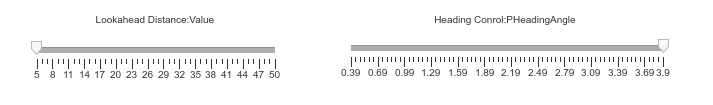

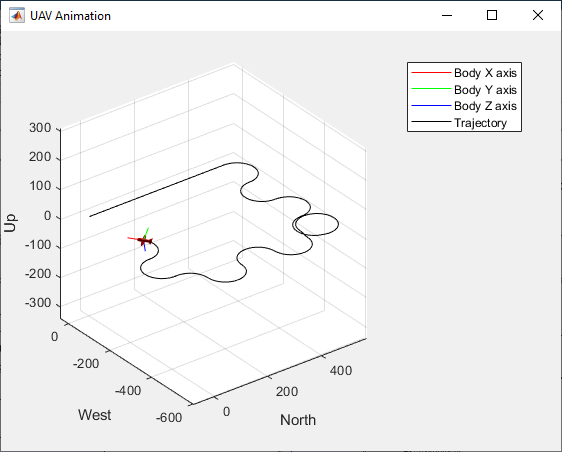

The next figure shows the flight behavior with a large lookahead distance and slow heading control.

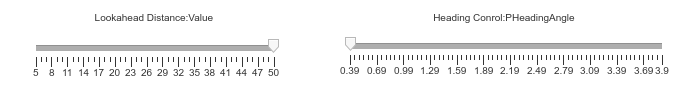

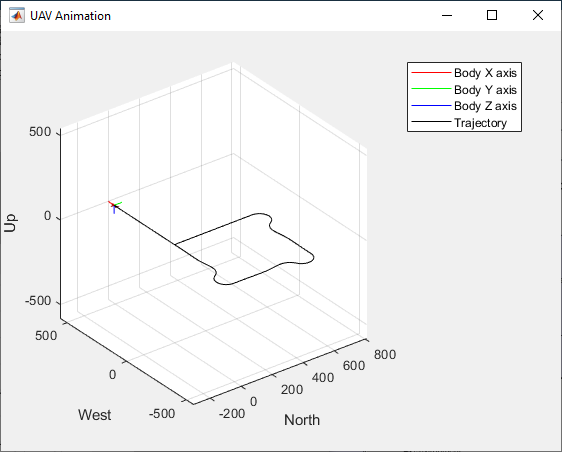

## Summary

This example tunes UAV flight controller by manually iterating through multiple sets of control parameters. This process can be extended to automatically sweep large set of control parameters to obtain optimal control configurations for customized navigation controllers.

Once the flight behavior satisfies design specification, consider testing the chosen control parameters with high-fidelity models built with Aerospace Blockset or with external flight simulators.

% close Simulink models
close_system("uavStepResponse");
close_system("fixedWingPathFollowing");

*Copyright 2020 The MathWorks, Inc.*